clear;
close all; 
 


data1 = readmatrix('albuminData.csv'); 
% data1 = readmatrix('reagentData.csv');

calibrationData = readmatrix('Calibrate/calibrationData.csv');


%signal Data
spec_data = data1(:, 2:end);
%max value of data to normalize
mVal = max(max(spec_data))

mVal = 85

spec_data1 = spec_data./mVal + calibrationData;

% spec_data = data2(:, 2:end);
% %max value of data to normalize
% mVal = max(max(spec_data))
% spec_data2 = spec_data./mVal + calibrationData;

data = [data1(:, 1),spec_data1 ];%; data2(:, 1),spec_data2 ]
data = sortrows(data, 1, "ascend");
spec_data = data(:, 2:end);
%label Data
lData = data(:, 1);

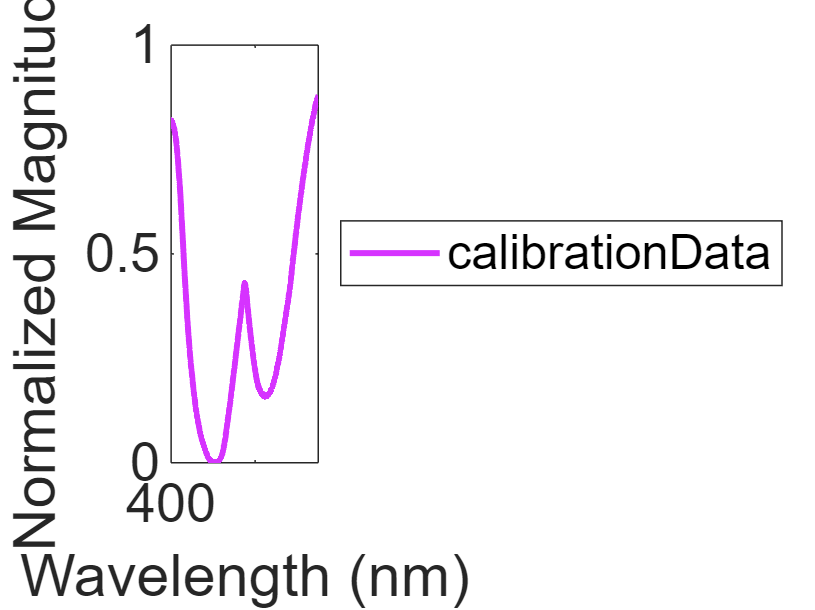


y = length(spec_data(1, :));
x = length(lData);
t = (1:y); 

wv = linspace(400, 750, y);

createFigure(wv, calibrationData, "calibrationData")
xlim([400 750])

sData = zeros(x, y);
%order= 11; 
%window = 25;
order= 9; 
window = 21;
for i = 1:x
    p = spec_data(i, :);
    p = smoothdata(p, 'movmedian', window);
    p = sgolayfilt(p, order, window);
    sData(i, :) = p; 
end



ul = -1;
samp = 50;
ppm = unique(lData);
for i = 1:length(ppm)
    tmp = num2str(ppm(i)) + " mg/dL";
    labels(i) = {tmp};
end

nConditions = length(labels); 
indeces = zeros(0, nConditions);
lbls = zeros(0, nConditions);
j = 1; 

for i=1:x
    if(lData(i) ~= ul)
        ul = lData(i);
        l = lData(i) * 2 ;
        lbls(j) = l;
        indeces(j) = i;
        j = j+1;
    end
end



 endInx = {}; 
 for i=1:nConditions
     if(i ~= nConditions)
         a = indeces(i);
         b = indeces(i+1)-1;
         endInx{i} = [a:b];
     else
         a = indeces(i);
         b = x;
         endInx{i} = [a:b];
     end
 end



[Xsorted,I] = sort(lbls);
indeces = indeces(I);
endInx = endInx(I);

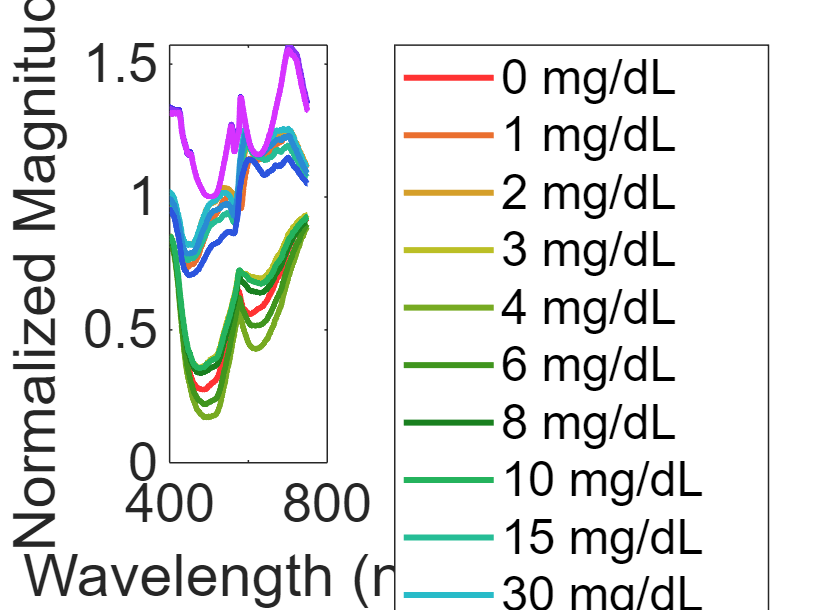

a2plot = sData(indeces, :);

createFigure(wv, a2plot, labels);

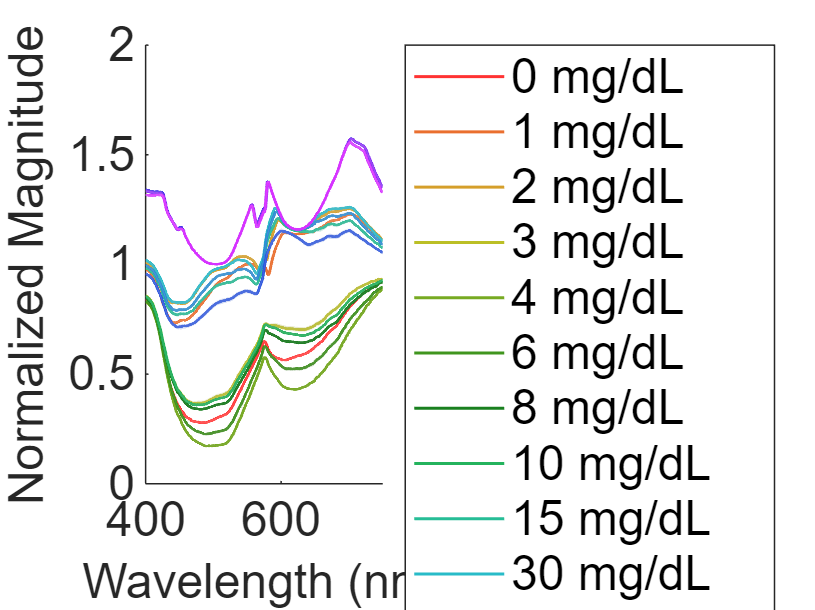

figure;
hueColor = linspace(0,0.8,nConditions);

hsvColor = ones(3,nConditions);
hsvColor(1,:) = hueColor;
hsvColor(2,:) = 0.8*hsvColor(2,:);

if nConditions > 3

    valueFront = linspace(1, 0.5, floor(nConditions/2));
    valueBack = linspace(0.7, 1, ceil(nConditions/2));
    valueColor = [valueFront,valueBack];
    hsvColor(3,:) = valueColor;
end

rgbColor = hsv2rgb(hsvColor');

hsvArea = hsvColor;

hsvArea(2,:) = hsvArea(2,:)*0.5;

rgbArea = hsv2rgb(hsvArea');

% colororder(rgbColor);

hold on
for i = 1:nConditions
    involved_data = sData(endInx{i},:);
    max_bound = max(involved_data,[],1);
    min_bound = min(involved_data,[],1);
    med_bound = median(involved_data,1);

    pgon = polyshape([wv,fliplr(wv)],[max_bound,fliplr(min_bound)],'Simplify',false,'KeepCollinearPoints',true);

    % plot(wv,max_bound,'HandleVisibility','off','Color',rgbArea(i,:))
    % 
    % plot(wv,min_bound,'HandleVisibility','off','Color',rgbArea(i,:))
    
    plot(wv,med_bound,'LineWidth',1,'Color',rgbColor(i,:))

    plot(pgon,"FaceColor",rgbArea(i,:),'EdgeColor','none','HandleVisibility','off')

end
legend(labels,'Location','eastoutside')
% Create ylabel
ylabel({'Normalized Magnitude'});

% Create xlabel
xlabel({'Wavelength (nm)'});
fontsize(16,"points")
xlim([400 750])
hold off

%%Summary Stats per class
m = max(max(sData));

stdData = zeros(nConditions, y);
% skewData = zeros(nConditions, y);
% kurtData = zeros(nConditions, y);
j = j; 
for i=1:nConditions
    for j = 1:y
        stdData(i, j) = std(sData(endInx{i},j)./m);
%         skewData(i, j) = skewness(sData(endInx{i},j));
%         kurtData(i, j) = kurtosis(sData(endInx{i},j));
    end
end

%a2plot = stdData;
%createFigure(wv, a2plot, labels);



sdData_all = zeros(1, y);
for i = 1:y
    sdData_all(i) = std(sData(:,i))/m;
end

pData = zeros(x, y);
 
for i = 1:x
   p = sData(i, :);
   [xp, yp] = prepareCurveData( t, p );
  
   [p,s,mu] = polyfit(xp,yp,21);
   pData(i, :) = polyval(p,t,[],mu);
end


% standard normal varient
% mean centers and divides by std of each spectra
 snvData = zeros(x, y);
 windowSize = 75; 
 order = 3; 
 for i = 1:x
     p = pData(i, :);
     p = sgolayfilt(p, order, windowSize);
     p = smoothdata(p, 'movmedian', windowSize);
     snv = SNV(p);
     snvData(i, :) = snv;
end


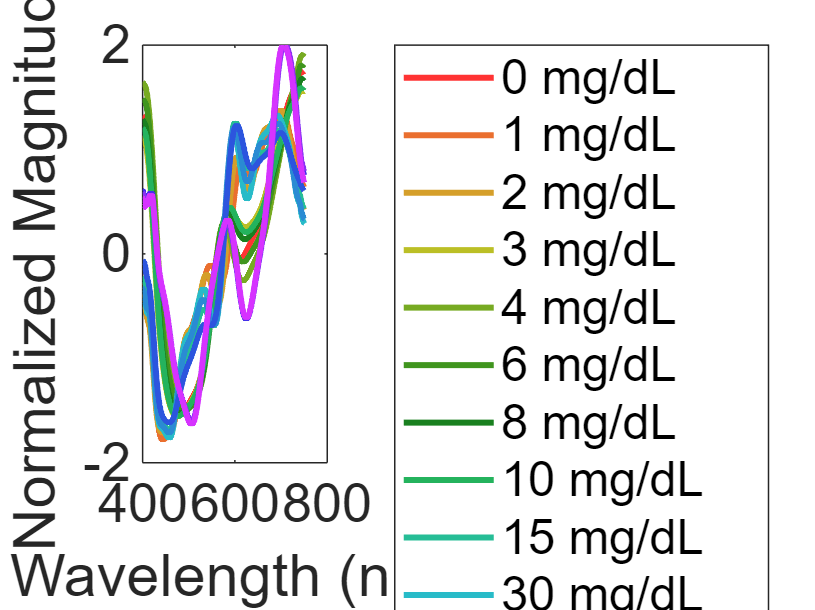


a2plot = snvData(indeces, :);
createFigure(wv, a2plot, labels);

%numerial gradient to get first derivative 
dxData = zeros(x, y);
windowSize = 75; 
order = 3; 

for i = 1:x
    p = pData(i, :);
    d = smoothdata(p, 'movmedian', windowSize);
    dx = gradient(p);
    dx = sgolayfilt(dx, order, windowSize);
    dx = smoothdata(dx, 'movmedian', windowSize);
    dxData(i, :) = dx;
end


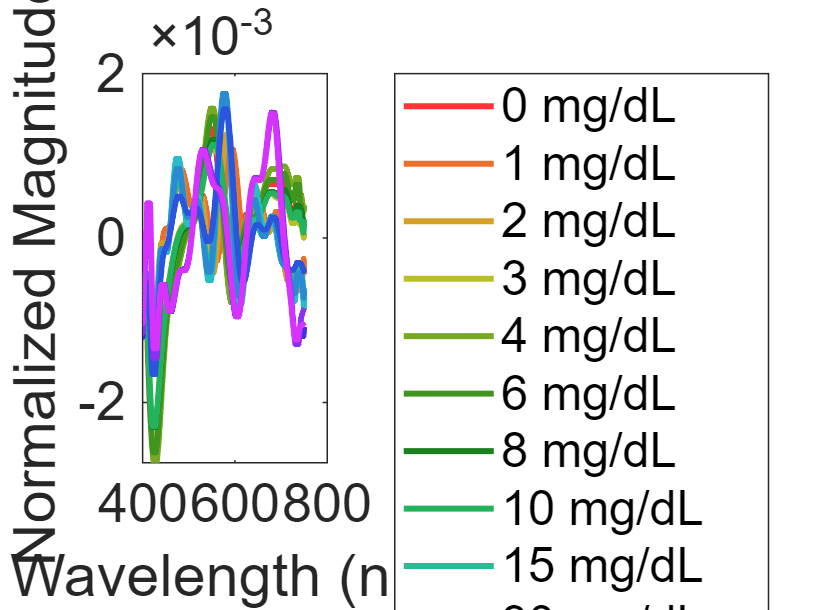


a2plot = dxData(indeces, :);
createFigure(wv, a2plot, labels);

%Second Derivaive
dx2Data = zeros(x, y);

for i = 1:x
    p = dxData(i, :);
    dx = gradient(p);
    dx = sgolayfilt(dx, order, windowSize);
    dx = smoothdata(dx, 'movmedian', windowSize);
    dx2Data(i, :) = dx;
end


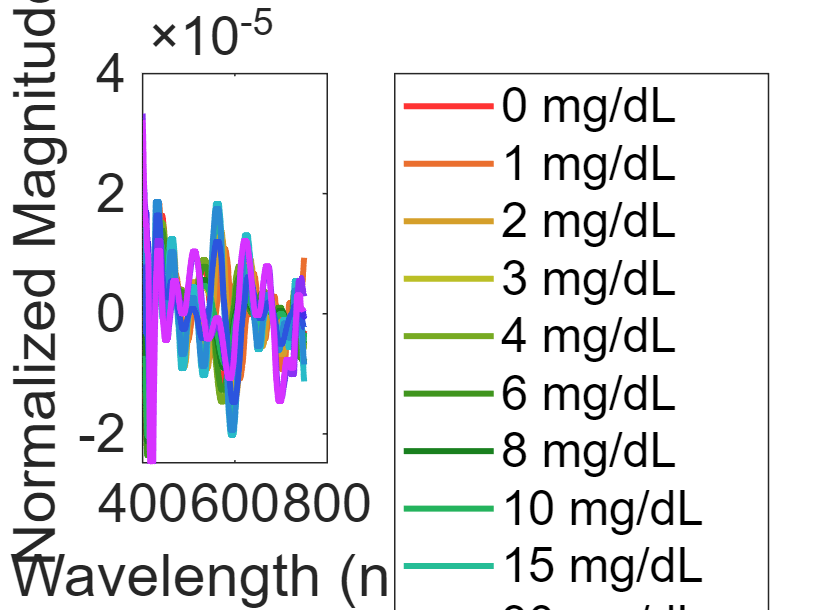


a2plot = dx2Data(indeces, :);
createFigure(wv, a2plot, labels);

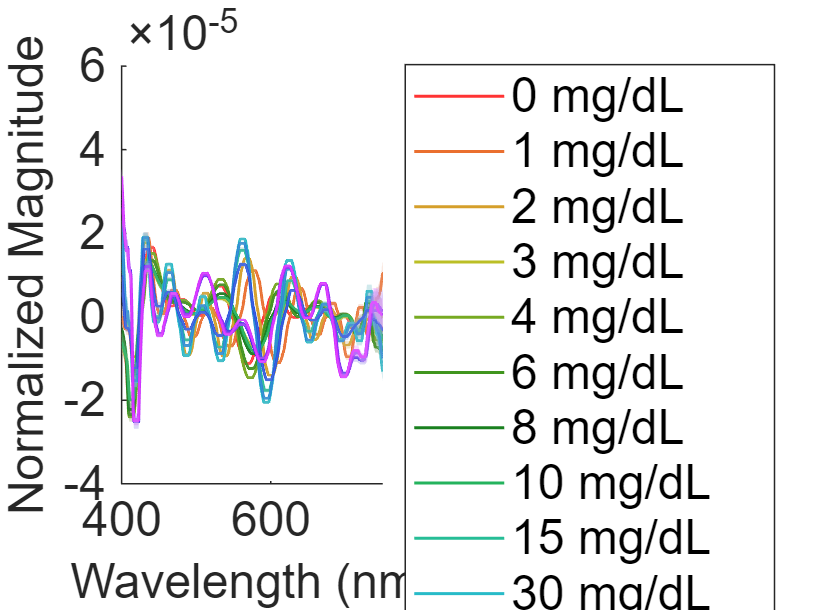

med_dx2Data = zeros(nConditions,y);

figure;
hueColor = linspace(0,0.8,nConditions);

hsvColor = ones(3,nConditions);
hsvColor(1,:) = hueColor;
hsvColor(2,:) = 0.8*hsvColor(2,:);

if nConditions > 3

    valueFront = linspace(1, 0.5, floor(nConditions/2));
    valueBack = linspace(0.7, 1, ceil(nConditions/2));
    valueColor = [valueFront,valueBack];
    hsvColor(3,:) = valueColor;
end

rgbColor = hsv2rgb(hsvColor');

hsvArea = hsvColor;

hsvArea(2,:) = hsvArea(2,:)*0.5;

rgbArea = hsv2rgb(hsvArea');

% colororder(rgbColor);

hold on
for i = 1:nConditions
    involved_data = dx2Data(endInx{i},:);
    max_bound = max(involved_data,[],1);
    min_bound = min(involved_data,[],1);
    med_bound = median(involved_data,1);
    med_dx2Data(i,:) = med_bound;

    pgon = polyshape([wv,fliplr(wv)],[max_bound,fliplr(min_bound)],'Simplify',false,'KeepCollinearPoints',true);

    % plot(wv,max_bound,'HandleVisibility','off','Color',rgbArea(i,:))
    % 
    % plot(wv,min_bound,'HandleVisibility','off','Color',rgbArea(i,:))
    
    plot(wv,med_bound,'LineWidth',1,'Color',rgbColor(i,:))

    plot(pgon,"FaceColor",rgbArea(i,:),'EdgeColor','none','HandleVisibility','off')

end
legend(labels,'Location','eastoutside')
% Create ylabel
ylabel({'Normalized Magnitude'});

% Create xlabel
xlabel({'Wavelength (nm)'});
fontsize(16,"points")
xlim([400 750])
hold off

%X = sData;
% X = pData;
X = snvData;
%X = [dxData];
%X = dx2Data;
Y = lData;


nComponents = 30;
nFolds = 10; 
[n,p] = size(X);
%[Xl,Yl, Xs,Ys,beta,pctVar, PLSmsep] = plsregress(X,Y,nComponents, 'cv', cvpartition(length(Y),'Leaveout'));
[Xl,Yl, Xs,Ys,beta,pctVar,MSE, stats] = plsregress(X,Y,nComponents, 'CV', nFolds);
%[Xl,Yl, Xs,Ys,beta,pctVar,MSE, stats] = plsregress(X,Y,nComponents, 'cv', cvpartition(length(Y),'HoldOut',0.3));

yfitPLS = [ones(n,1) X]*beta;

TSS = sum((Y-mean(Y)).^2);
RSS_PLS = sum((Y-yfitPLS).^2);
rsquaredPLS = 1 - RSS_PLS/TSS

rsquaredPLS = 0.9981


err_PLS = Y-yfitPLS;

mse_PLS = mean(err_PLS.^2);
rmse_PLS = sqrt(mse_PLS)

rmse_PLS = 11.8525

mae_PLS = mae(err_PLS)

mae_PLS = 8.4985

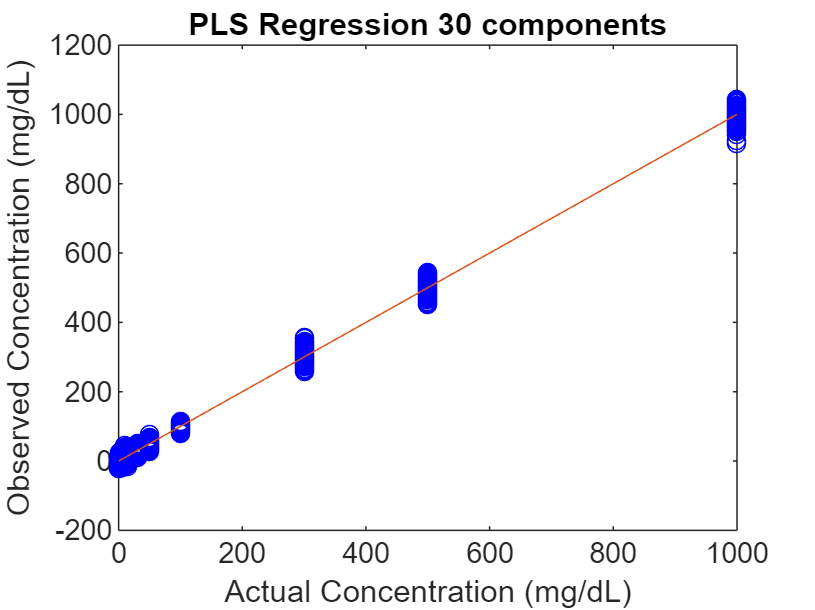

% plot(Y,yfitPLS,'bo',Y,yfitPCR,'r^');
plot(Y,yfitPLS,'bo', Y, Y);
xlabel('Actual Concentration (mg/dL)');
ylabel('Observed Concentration (mg/dL)');
% legend({'PLSR with 10 components' 'PCR with 10 Components'},'location','NW');
title('PLS Regression 30 components');


[components, idx] = sort(abs(beta), "descend");

waveLengths = (idx./y * 350) + 400 - 0.1463;


pComp = [waveLengths(1:30),components(1:30)]';
pComp = round(pComp, 2, "decimals");



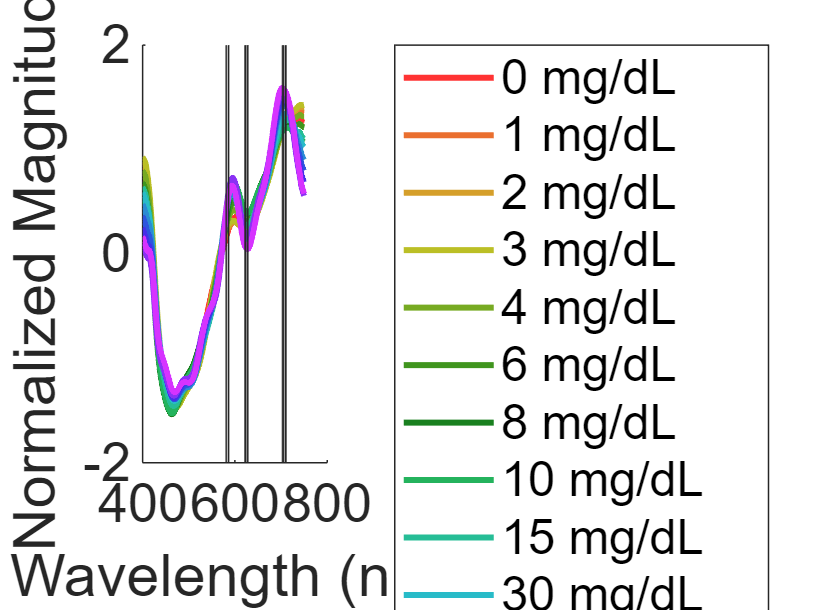

a2plot = smoothdata(X(indeces, :), "gaussian");
a2plot = smoothdata(X(indeces, :), "movmean", 10);
createFigure(wv, a2plot, labels);
hold on
for i = 1:length(pComp)
    h(i) = xline(pComp(1,i));
    set( get( get(h(i), 'Annotation'), 'LegendInformation' ), 'IconDisplayStyle', 'off' );
end
hold off
box("off")

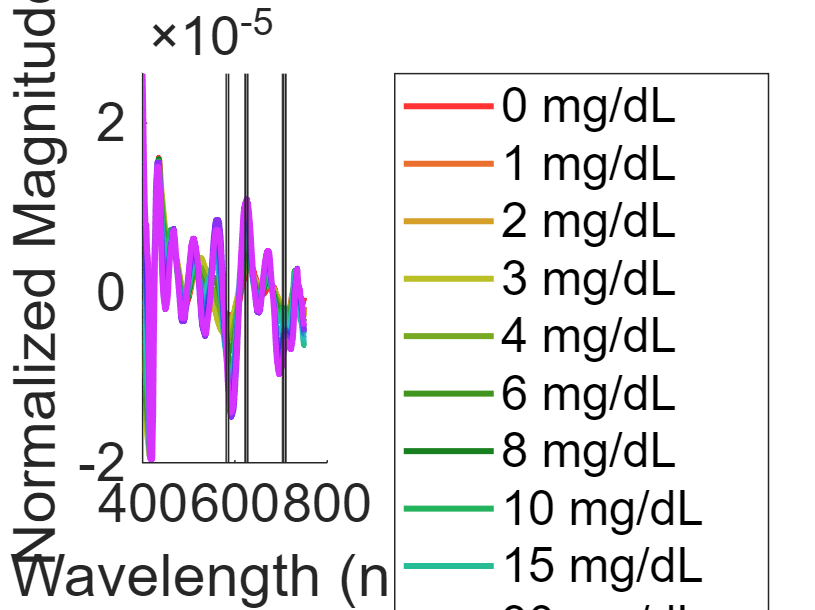

a2plot = smoothdata(med_dx2Data, "movmean", 10);

createFigure(wv, a2plot, labels);
hold on
for i = 1:length(pComp)
    h(i) = xline(pComp(1,i));
    set( get( get(h(i), 'Annotation'), 'LegendInformation' ), 'IconDisplayStyle', 'off' );
end
hold off
box("off")

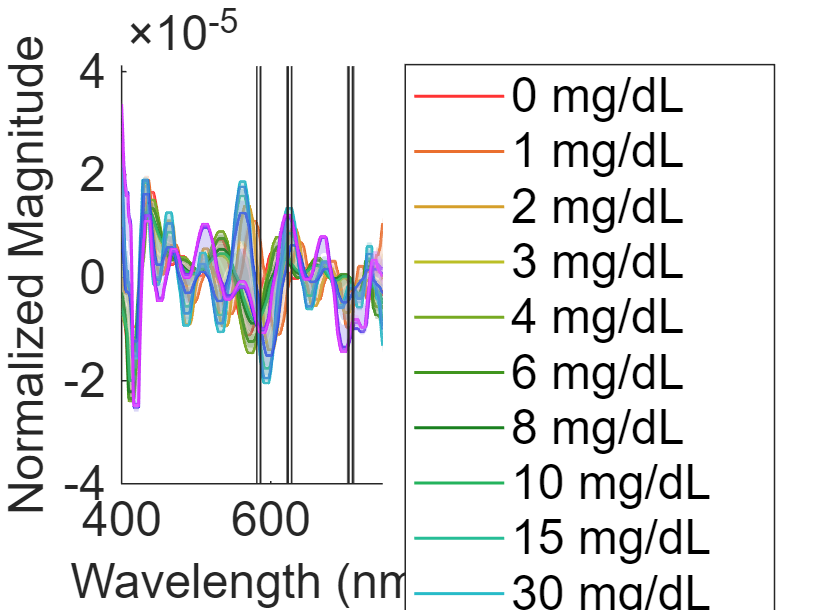

smoothdx2data = smoothdata(dx2Data, "movmean", 10);
figure;
hueColor = linspace(0,0.8,nConditions);

hsvColor = ones(3,nConditions);
hsvColor(1,:) = hueColor;
hsvColor(2,:) = 0.8*hsvColor(2,:);

if nConditions > 3

    valueFront = linspace(1, 0.5, floor(nConditions/2));
    valueBack = linspace(0.7, 1, ceil(nConditions/2));
    valueColor = [valueFront,valueBack];
    hsvColor(3,:) = valueColor;
end

rgbColor = hsv2rgb(hsvColor');

hsvArea = hsvColor;

hsvArea(2,:) = hsvArea(2,:)*0.5;

rgbArea = hsv2rgb(hsvArea');

% colororder(rgbColor);
axes1 = axes('Parent',figure);

hold on
for i = 1:nConditions
    involved_data = smoothdx2data(endInx{i},:);
    max_bound = max(involved_data,[],1);
    min_bound = min(involved_data,[],1);
    med_bound = median(involved_data,1);

    pgon = polyshape([wv,fliplr(wv)],[max_bound,fliplr(min_bound)],'Simplify',false,'KeepCollinearPoints',true);

    % plot(wv,max_bound,'HandleVisibility','off','Color',rgbArea(i,:))
    % 
    % plot(wv,min_bound,'HandleVisibility','off','Color',rgbArea(i,:))
    
    plot(wv,med_bound,'LineWidth',1,'Color',rgbColor(i,:))

    plot(pgon,"FaceColor",rgbArea(i,:),'EdgeColor','none','HandleVisibility','off')
end

for i = 1:length(pComp)
    h(i) = xline(pComp(1,i));
    set( get( get(h(i), 'Annotation'), 'LegendInformation' ), 'IconDisplayStyle', 'off' );
end

legend(labels,'Location','eastoutside')
% Create ylabel
ylabel({'Normalized Magnitude'});

% Create xlabel
xlabel({'Wavelength (nm)'});
fontsize(16,"points")
xlim([400 750])
hold off
box("off")

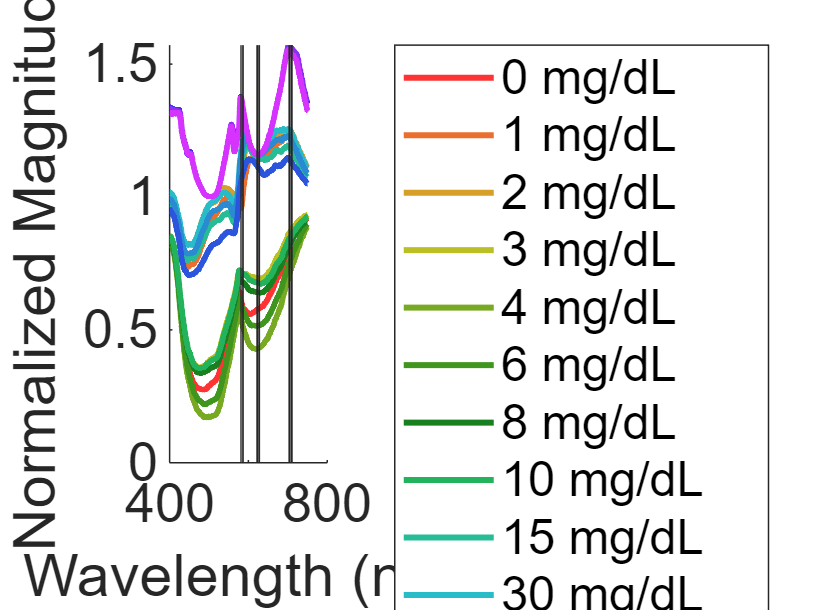

a2plot = sData(indeces, :);
createFigure(wv, a2plot, labels);
hold on
for i = 1:length(pComp)
    h(i) = xline(pComp(1,i));
    set( get( get(h(i), 'Annotation'), 'LegendInformation' ), 'IconDisplayStyle', 'off' );

end
hold off
box("off")

figure;
hueColor = linspace(0,0.8,nConditions);

hsvColor = ones(3,nConditions);
hsvColor(1,:) = hueColor;
hsvColor(2,:) = 0.8*hsvColor(2,:);

if nConditions > 3

    valueFront = linspace(1, 0.5, floor(nConditions/2));
    valueBack = linspace(0.7, 1, ceil(nConditions/2));
    valueColor = [valueFront,valueBack];
    hsvColor(3,:) = valueColor;
end

rgbColor = hsv2rgb(hsvColor');

hsvArea = hsvColor;

hsvArea(2,:) = hsvArea(2,:)*0.5;

rgbArea = hsv2rgb(hsvArea');

% colororder(rgbColor);

hold on
for i = 1:nConditions
    involved_data = sData(endInx{i},:);
    max_bound = max(involved_data,[],1);
    min_bound = min(involved_data,[],1);
    med_bound = median(involved_data,1);

    pgon = polyshape([wv,fliplr(wv)],[max_bound,fliplr(min_bound)],'Simplify',false,'KeepCollinearPoints',true);

    % plot(wv,max_bound,'HandleVisibility','off','Color',rgbArea(i,:))
    % 
    % plot(wv,min_bound,'HandleVisibility','off','Color',rgbArea(i,:))
    
    plot(wv,med_bound,'LineWidth',1,'Color',rgbColor(i,:))

    plot(pgon,"FaceColor",rgbArea(i,:),'EdgeColor','none','HandleVisibility','off')

end
legend(labels,'Location','eastoutside')
% Create ylabel
ylabel({'Normalized Magnitude'});

% Create xlabel
xlabel({'Wavelength (nm)'});
fontsize(16,"points")
xlim([400 750])
hold off
box("off")